# MXB261 Problem Solving Task

% Two arrays, one for all cases N = 100, one for all cases N = 200
p_N100 = zeros(2, 100, 8);
p_N200 = zeros(2, 200, 8);

for i = 1:4 % Loops over probability cases

    % SETTING PROBABILITY
    if i == 1       % case i)------------]
        s = 1/3; w = s;     e = s; %    -]
    elseif i == 2   % case ii)          -]
        s = 2/3; w = 1/6;   e = 1/6; %  -]
    elseif i == 3   % case iii)         -]
        s = 3/5; w = 3/10;  e = 1/10; % -]
    else            % case iv)          -]
        s = 3/5; w = 1/10;  e = 3/10; % -]
    end %--------------------------------]

    for j = 1:2 % Loops over starting position cases

        % SETTING STARTING POSITION
        if j == 1 % -------]
            P = 1;      % -]
        else            % -]
            P = 'rand'; % -]
        end % -------------]

        % GENERATING RESULTS
        [p_N100(:,:, 2*i - 2 + j), ~] = accretion(P, 100, s,w,e);
        [p_N200(:,:, 2*i - 2 + j), ~] = accretion(P, 200, s,w,e);
    end
end 

We can look at what this generates with the following code snippet

% trimmed_mask = accreted_mask(70:99, :); % Trimming some of the empty part
% imshow(~trimmed_mask,'InitialMagnification','fit') % Inverted so =true displays black

## HISTOGRAMS

Create a 2x2 subplot, with the different probabilities inside

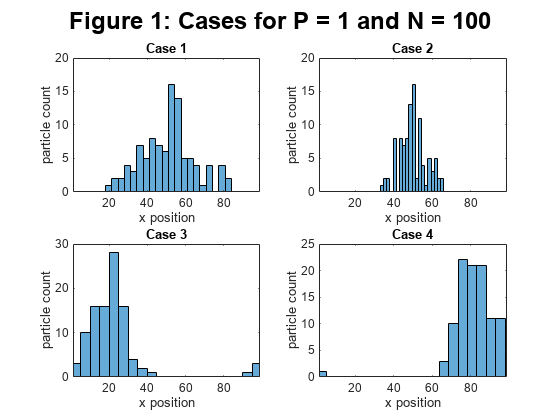

bins = 20; % 20 looks way cooler

P1_N100_figure = figure;
for i = 1:4 % Plotting case i, ii, iii and iv for P = 1 and N = 100
    subplot(2,2, i);
    histogram(p_N100(1,:, i*2 - 1), bins); % P = 1 on odd numbers
    title(sprintf('Case %d', i));
    xlabel('x position');
    ylabel('particle count');
    xlim([1 99])
end
P1_N100_title = sgtitle('Figure 1: Cases for P = 1 and N = 100');
P1_N100_title.FontSize = 18; P1_N100_title.FontWeight = "bold";

P1_N200_figure = figure;
for i = 1:4 % Plotting case i, ii, iii and iv for P = 1 and N = 200
    subplot(2,2, i);
    histogram(p_N200(1,:, i*2 - 1), bins); % P = 1 on odd numbers
    title(sprintf('Case %d', i));
    xlabel('x position');
    ylabel('particle count');
    xlim([1 99])
end
P1_N200_title = sgtitle('Figure 2: Cases for P = 1 and N = 200');
P1_N200_title.FontSize = 18; P1_N200_title.FontWeight = "bold";

PR_N100_figure = figure;
for i = 1:4 % Plotting case i, ii, iii and iv for P = 'rand' and N = 100
    subplot(2,2, i);
    histogram(p_N100(1,:, i*2), bins); % P = 'rand' on even numbers
    title(sprintf('Case %d', i));
    xlabel('x position');
    ylabel('particle count');
    xlim([1 99])
end
PR_N100_title = sgtitle("Figure 3: Cases for P = 'rand' and N = 100");
PR_N100_title.FontSize = 18; PR_N100_title.FontWeight = "bold";

PR_N200_figure = figure; 
for i = 1:4 % Plotting case i, ii, iii and iv for P = 'rand' and N = 200
    subplot(2,2, i);
    histogram(p_N200(1,:, i*2), bins); % P = 'rand' on even numbers
    title(sprintf('Case %d', i));
    xlabel('x position');
    ylabel('particle count');
    xlim([1 99])
end
PR_N200_title = sgtitle("Figure 4: Cases for P = 'rand' and N = 200");
PR_N200_title.FontSize = 18; PR_N200_title.FontWeight = "bold";

% Saving figures as images
saveas(P1_N100_figure, 'Figure_1.png')

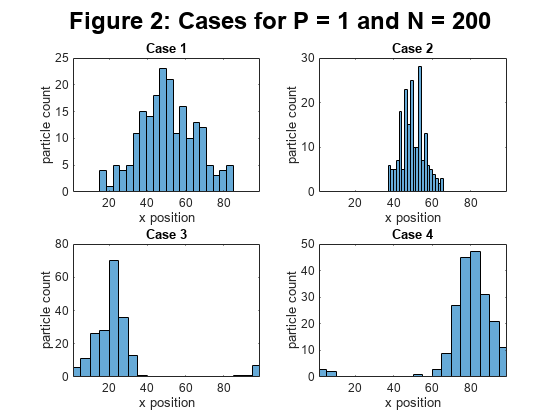

saveas(P1_N200_figure, 'Figure_2.png')

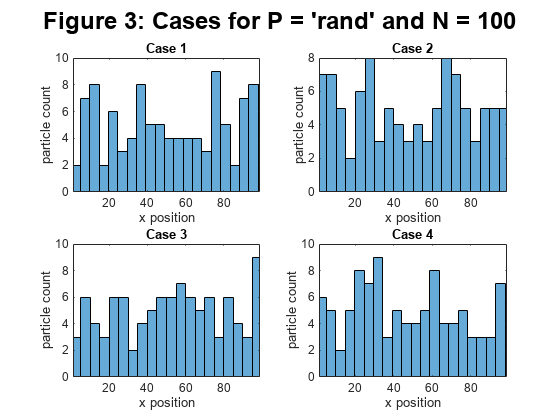

saveas(PR_N100_figure, 'Figure_3.png')

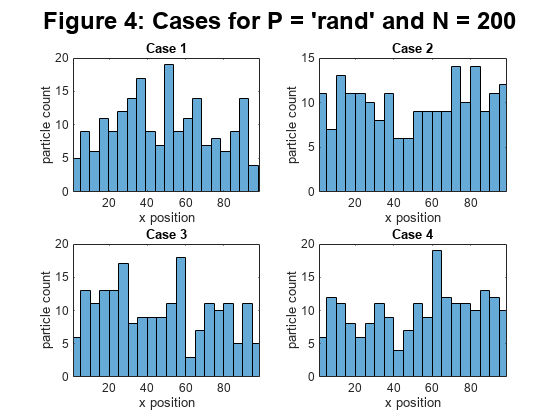

saveas(PR_N200_figure, 'Figure_4.png')

function [particles, accreted_mask] = accretion(P, N, s, w, e)
% ACCRETION - Biased random walk of falling and accreting particles
% particles = accretion(P,N,s,w,e) takes N many particles beginning at a
% starting point y = 99, x = [1,99] determined by P, and 'drops' them
% until they hit the bottom, or accrete onto another fallen particle. This
% fall is a biased random walk. A particle will move; south (-y) at
% probability s, west (-x) at probability w, and east (+x) at 
% probability e.
% The function outputs particles, a 2xN array of final positions of all
% particles; and accreted_mask, the collision mask (another way of
% communicating particle positions).
% Assumes P == 1 or 'rand'. Assumes s + w + e == 1.

domain = 99; % Set by the question, but it's useful to have here
p = cumsum([s,w,e]); % Cumulative sums of the probabilities

boundary = false([domain,domain+1]); % Records the final position of particles
%^% NOTE!! For boundary; dim=1 is the x-coordinate, dim=2 is y + 1 
boundary(:,1) = 1; % Adding a collision boundary along y = 0 (y+1=1)
% boundary is the collision mask, particles will check against this to see
% if a position they intend to move into is already occupied. There is
% collision set along the bottom of the domain (so particles do not fall
% endlessly), and once a particle reaches its final position, it will be
% added to the collision mask

particles = zeros([2,N], 'int8'); % x = row1, y = row2; dim=2 is particle number
particles(2,:) = domain; % Setting y = 99 for all particles
% particles records the position of each N particles, in terms of x and y
% coordinates. As such, by the end of the function, particles contains the
% final positions.

if P == 1 % Applying start conditions for x
    particles(1,:) = 50; % All particles begin at x = 50
elseif isequal(P,'rand')
    particles(1,:) = randi([1,domain], 1,N); % x = N random integers from 1-99 
else
    error("Input error. P can only be 1 or 'rand'.")
end

for i = 1:N % Looping over each particle

    % Initialising while loop
    rest = false; % There are valid moves for particle i
    south = false; west = false; east = false; % Particle hasn't moved yet!
    safety_switch = 0;
    while rest == false % Looping until particle i can no longer move.

        %-------SAFETY SWITCH----------------]
        safety_switch = safety_switch + 1; % ]
        if safety_switch > 10^6            % ]
            safety_switch = 0, break       % ]
        end %---SAFETY SWITCH----------------]
        % Because while loops can get out of hand; this will break the loop
        % if it iterates too many times (i.e., if it's not actually
        % progressing towards the end of the loop), and will output
        % safety_switch = 0 since it ends in "," not ";"
        
        u = rand; % Determining a direction
        if u <= p(1) || (west && east) 
        % MOVING SOUTH
        % If there are collisions to the east and west, ignore the
        % randomiser and check south.
            target = particles(:,i) + int8([0; -1]); 
            south = true;
        elseif (u <= p(2) && ~west) || east 
        % MOVING WEST 
        % If there is a collision west, ignore the randomiser and skip. If
        % there is a collision east (and you already skipped south), ignore
        % the randomiser and check west.
            target = particles(:,i) + int8([-1; 0]); 
            west = true;
        elseif u <= p(3) || west 
        % MOVING EAST
        % If there is a collision to the west, ignore the randomiser and
        % check east.
            target = particles(:,i) + int8([1; 0]); 
            east = true;
        end
        
        wrap_left2right = domain * int8(target(1) < 1);
        wrap_right2left = domain * int8(target(1) > domain);
        target(1) = target(1) + wrap_left2right - wrap_right2left;
        % If x <= 0, +domain (to loop back around to x <= domain)
        % If x > domain, -domain (to loop back around to x >= 1)
        % We're only applying this to x because;
        %   1. There is no +y movement
        %   2. We want y = 0 to exist so it triggers the boundary there
        collision = boundary(target(1), target(2)+1);

        if collision && south % Collides with something south
            boundary(particles(1,i), particles(2,i)+1) = true;
            rest = true; % There are no valid moves for particle i
        elseif ~collision % No collisions
            % If there is a collision, particle position is not updated and
            % that direction will be set =true at the start of the loop.
            south = false;
            west = false;
            east = false;
            particles(:,i) = target; % Free to move!
        end 
    end
end
accreted_mask = flip(boundary'); % Orienting such that north = up, west = left, etc.
end